**Por favor, antes de realizar la actividad cambie el nombre del live script a uno que contenga las iniciales de los integrantes del grupo. Esto me permitirá diferenciar los archivos entregados en plataforma. De la misma manera, no olvide  ajustar el nombre del modelo a desarrollar en Simulink a fin de que incluya las iniciales de las personas que lo presentan.**

# **Logaritmos en Matlab**

En esta actividad, usted desarrollará las instrucciones para obtener los valores que se solicitan en cada punto

Nombre 1: JUAN ESTEBAN DIAZ DELGADO

Nombre 2: NICOLAS ANDRES YATE VARGAS

## Part I

(3 points)

       1 . Cree un vector x de 100 elementos 1 hasta 1000000 con la función linspace

X =linspace(1,1000000,100)

X =            1       10102       20203       30304       40405       50506       60607       70708       80809       90910      101011      111112      121213      131314      141415      151516      161617      171718      181819      191920      202021      212122      222223      232324      242425      252526      262627      272728      282829      292930      303031      313132      323233      333334      343435      353536      363637      373738      383839      393940      404041      414142      424243      434344      444445      454546      464647      474748      484849      494950


        2.  Cree un vector y de 100 elementos 1 hasta 1000000 con la función logspace

y=logspace(1,1000000,100)

y =     10   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf


        3.  ¿Cómo se diferencian los vectores x y y creados en los pasos 2 y 3?

Respuesta:: La diferencia es que en vector en X es un vector lineal creado con la linespace la cual que crea un vector lineal y el vector en Y es una vector logatirmico en base 10, utilizado normalmente para realizar trabajos de frecuencia .

        4. Realice 3 graficos utilzando las funciones plot, semilogx, y loglog de la función f(x) = x^2. Por favor utilice la instrucción tiledlayout para crear en la parte superior la grafica con la función plot, seguida el gráfico con la instrucción semilog y por último la función loglog

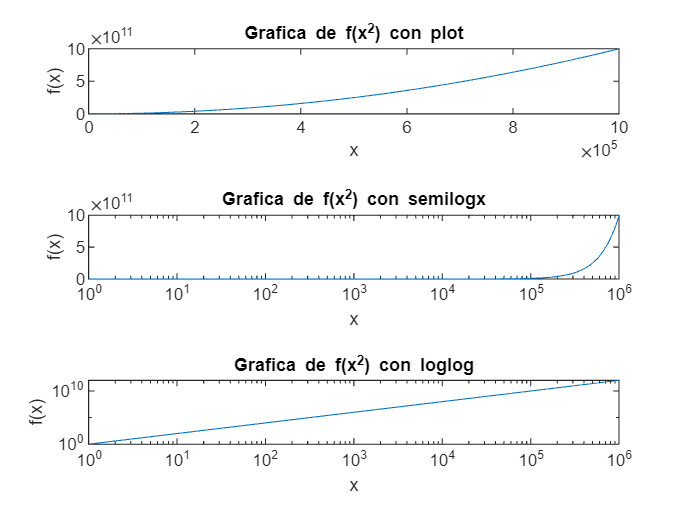

f= X.^2;
tiledlayout(3,1)

nexttile;
plot(X,f)
title('Grafica de f(x^2) con plot')
xlabel('x')
ylabel('f(x)')


nexttile;
semilogx(X,f)
title('Grafica de f(x^2) con semilogx')
xlabel('x')
ylabel('f(x)')


nexttile;
loglog(X,f)
title('Grafica de f(x^2) con loglog')
xlabel('x')
ylabel('f(x)')

## Part II

(7 points)

En sesiones presenciales anteriores se vieron circuitos en serie y paralelo resonantes. 

- Diseñe un circuito resonante (un serie y uno paralelo) que presente una frecuencia de resonancia al rededor de los 65 kHz. 

- Cree un modelo en Simulink y verifique que la condición de resonancia a 65 kHz

- Utilice este live script para crear un vector de frecuencias desde 1 Hz hasta 1 MHz logaritmicamente espaciado de al menos 100 valores. Tenga presente el paso 2 de la parte I.

- Utilice el vector creado en el paso 3 (de esta sección) para ejecutar la simulación del circuito resonante y registrar las magnitudes de interés en los circuitos resonantes para las 100 frecuencias del vector de frecuencia creada en el paso 3. Tenga presente las clases previas para poder escoger las magnitudes de interés. **Las magnitudes escogidas deben exportarse de manera automática a Matlab para que puedan ser accesibles desdeel Live script**

- Utilice el tiledlayout para graficar:

I. Para el circuito Serie

            a. corriente vs frecuencia

            b. Desfase de la corriente vs frecuencia 

            c. Voltaje en el inductor vs frecuencia 

            d. Voltaje en el capacitor vs frecuencia 

            e. Impedancia vs frecuencia (Teóricamente no por simulación)

            f. Admitancia vs frecuencia (Teóricamente no por simulación)

II. Para el circuito Serie

            a. Corriente de la fuente vs frecuencia

            b. Desfase de la corriente de la fuente vs frecuencia 

            c. Corriente de R, L y C vs frecuencia 

            d. Impedancia vs frecuencia (Teóricamente no por simulación)

            e. Admitancia vs frecuencia (Teóricamente no por simulación)

Consideraciones:

a. Aunque no se indica el tipo de gráfica a desarrollar, (lineal, semilog, loglog) usted debe seleccionar aquella que mejor pueda resaltar el comportamiento del circuito

Nota: 

- Recuerde anexar el modelo en simulink desarrollado

- Usted debe presentar y sustentar la actividad al final de la sesión. 

- No comparta el código creado.


%Datos circuito en serie
R = 2;
C = 400e-9

C = 4.0000e-07

Vs = 10;
Frequency = 65e3;
f = logspace(4, 6, 100);
w = 2*pi*Frequency;
Xc = 1/w*C;
L = 1/((2*pi*Frequency)^2*C)

L = 1.4988e-05

Xl = w*L;    
zt = R+1i*2*pi*f*L-1i./(2*pi*f*C);
zt = abs(zt);
admitancia_serie = 1./zt;

%Datos circuito en paralelo

Xl1 = 1i*2*pi*f*L;
Xc1 = -1i./(2*pi*f*C);
Impedancia_paralelo = 1./((1/R)+(1./Xc1)+(1./Xl1));
Impedancia_paralelo = abs(Impedancia_paralelo);
admitancia_paralelo = 1./Impedancia_paralelo;




f(40) = Frequency;

%información del circuito en serie

serie_magnitud_corriente = zeros(1,100);
serie_angulo_corriente = zeros(1,100);
serie_voltaje_del_inductor = zeros(1,100);
serie_voltaje_del_capacitor = zeros(1,100);

%información del circuito en paralelo 

paralelo_magnitud_corriente = zeros(1,100);
paralelo_angulo_corriente = zeros(1,100);
paralelo_corriente_del_resistor = zeros(1,100);
paralelo_corrinte_del_inductor = zeros(1,100);
paralelo_corriente_del_capacitor = zeros(1,100);


for i = 1:100

    Frequency = f(i);
    simula = sim('Simulacion_Resonante.slx');

    serie_magnitud_corriente(i) = simula.logsout{7}.Values.Data(end);
    serie_angulo_corriente(i) = simula.logsout{6}.Values.Data(end); 
    serie_voltaje_del_inductor(i) = simula.logsout{8}.Values.Data(end); 
    serie_voltaje_del_capacitor(i) = simula.logsout{9}.Values.Data(end);

    paralelo_magnitud_corriente(i)  = simula.logsout{2}.Values.Data(end);
    paralelo_angulo_corriente(i) = simula.logsout{1}.Values.Data(end);
    paralelo_corriente_del_resistor(i) = simula.logsout{4}.Values.Data(end); 
    paralelo_corrinte_del_inductor(i) = simula.logsout{3}.Values.Data(end); 
    paralelo_corriente_del_capacitor(i) = simula.logsout{5}.Values.Data(end); 


end



##  Graficos del circuito en serie

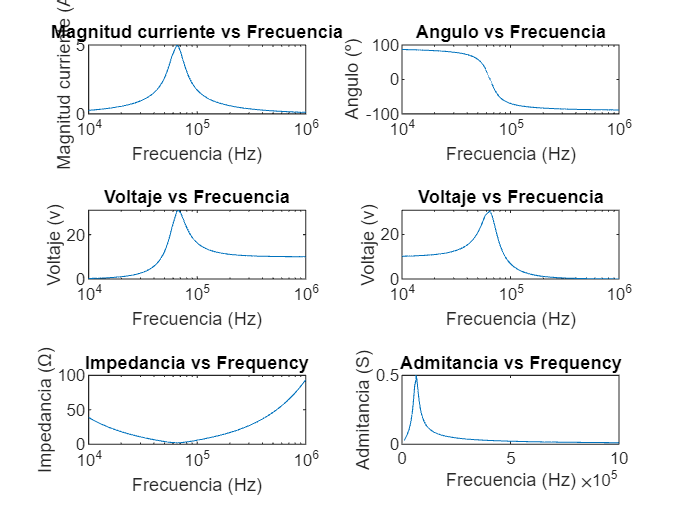


tiledlayout(3,2)

nexttile
semilogx(f,serie_magnitud_corriente)
title('Magnitud curriente vs Frecuencia')
xlabel('Frecuencia (Hz)')
ylabel('Magnitud curriente (A)')

nexttile
semilogx(f,serie_angulo_corriente)
title('Angulo vs Frecuencia')
xlabel('Frecuencia (Hz)')
ylabel('Angulo (º)')

nexttile
semilogx(f,serie_voltaje_del_inductor)
title('Voltaje vs Frecuencia')
xlabel('Frecuencia (Hz)')
ylabel('Voltaje (v)') 

nexttile
semilogx(f,serie_voltaje_del_capacitor)
title('Voltaje vs Frecuencia')
xlabel('Frecuencia (Hz)')
ylabel('Voltaje (v)') 

nexttile
semilogx(f,zt)
title("Impedancia vs Frequency")
xlabel("Frecuencia (Hz)")
ylabel("Impedancia (Ω)")

nexttile
plot(f,admitancia_serie)
title("Admitancia vs Frequency")
xlabel("Frecuencia (Hz)")
ylabel("Admitancia (S)")
hold off

## Graficos circuito en paralelo

valor = admitancia_paralelo

valor =     1.1510    1.1067    1.0647    1.0249    0.9873    0.9517    0.9181    0.8864    0.8565    0.8284    0.8018    0.7769    0.7535    0.7315    0.7110    0.6917    0.6737    0.6569    0.6413    0.6268    0.6133    0.6008    0.5892    0.5785    0.5687    0.5597    0.5514    0.5439    0.5371    0.5310    0.5255    0.5205    0.5162    0.5124    0.5092    0.5064    0.5042    0.5024    0.5012    0.5004    0.5000    0.5001    0.5007    0.5018    0.5033    0.5053    0.5078    0.5108    0.5143    0.5184


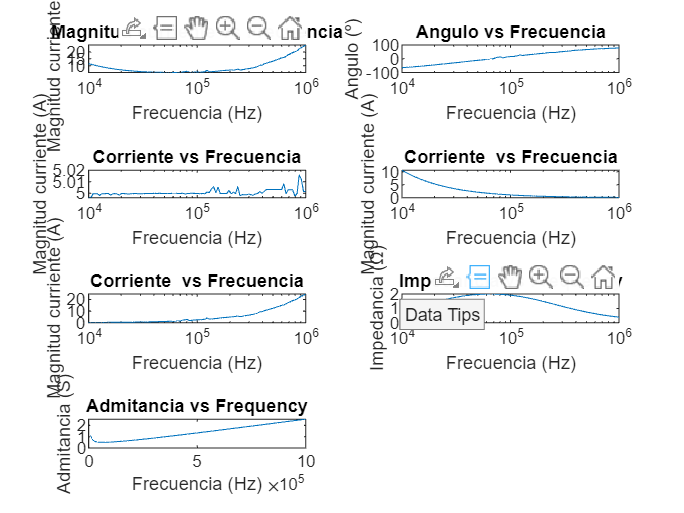

circuito_paralelo = tiledlayout(4,2);

nexttile
semilogx(f,paralelo_magnitud_corriente)
title('Magnitud curriente vs Frecuencia')
xlabel('Frecuencia (Hz)')
ylabel('Magnitud curriente  (A)')

nexttile
semilogx(f,paralelo_angulo_corriente)
title('Angulo vs Frecuencia')
xlabel('Frecuencia (Hz)')
ylabel('Angulo (º)')

nexttile
semilogx(f,paralelo_corriente_del_resistor)
title('Corriente vs Frecuencia')
xlabel('Frecuencia (Hz)')
ylabel('Magnitud curriente (A)') 

nexttile
semilogx(f,paralelo_corrinte_del_inductor)
title('Corriente  vs Frecuencia')
xlabel('Frecuencia (Hz)')
ylabel('Magnitud curriente (A)') 

nexttile
semilogx(f,paralelo_corriente_del_capacitor)
title('Corriente  vs Frecuencia')
xlabel('Frecuencia (Hz)')
ylabel('Magnitud curriente (A)') 

nexttile
semilogx(f,Impedancia_paralelo)
title("Impedancia vs Frequency")
xlabel("Frecuencia (Hz)")
ylabel("Impedancia (Ω)")

nexttile
plot(f,admitancia_paralelo)
title("Admitancia vs Frequency")
xlabel("Frecuencia (Hz)")
ylabel("Admitancia (S)")